%%this function implements the same thing as experiment 2
%but instead does it using my own personal recursive FFT algorithm

%sets the basic parameters for the audio input and outputs
SampleRate = 48000;
FrameSize = 1024;
NumChannels = 1;


%sets the limits of the plot
x_lower = 0;
x_upper = 10000;
y_lower = -10;
y_upper = 50;


%sets alpha, the coefficient we use to calculate the averaged power
alpha = 0.50;


%sets up the audioReader object
audioReader = audioDeviceReader('NumChannels',NumChannels, ...
    'BitDepth','24-bit integer', ...
    'SamplesPerFrame',FrameSize, ...
    'SampleRate',SampleRate);

%sets up the audio writer
audioWriter = audioDeviceWriter('SampleRate',SampleRate, ...
    'BufferSize', FrameSize, ...
    'BitDepth', '24-bit integer');

%this starts the recording of the data
disp('Starting Processing');

Starting Processing


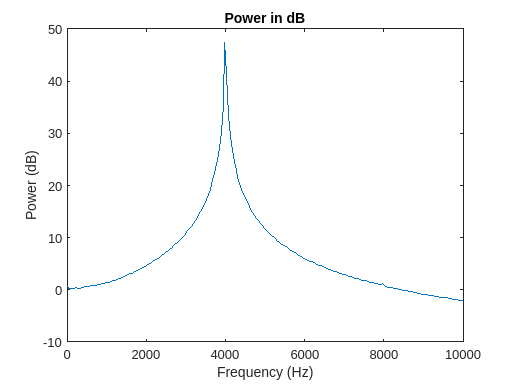



%creates array to store the current averaged power
currentAveragePower = zeros([FrameSize 1]);

%creates array to store the previous averaged power
previousAveragePower = zeros([FrameSize 1]);

tic
for i = 1:100
    
    %gets the audio data of one frame
    inputData = step(audioReader);
    
    dft = zeros([FrameSize 1]);
    
    %sets twiddle factor
    Wn = exp(-1j*2*pi/FrameSize);
    
    for k = 1:FrameSize
        sum = 0;

        for n = 1:FrameSize
            sum = sum + inputData(n)*(Wn^((k-1)*(n-1)));
        end
        dft(k) = sum;
    end

    %gets the instantaneous power of the inputDataFFT
    inputDataFFTPower = real(dft).*real(dft) + imag(dft).*imag(dft);
    


    %finds the current averaged power array
    currentAveragePower = (1-alpha).*inputDataFFTPower + alpha.*previousAveragePower;
    
    %sets the previous averaged power array to the current power array
    previousAveragePower = currentAveragePower;   

    %creates the space to go from zero hertz up to the sample rate
    x = linspace(0, SampleRate, FrameSize);

    %does the same plot, but now in dB
    plot(x,10*log10(currentAveragePower));
    hold on;
    title("Power in dB");
    xlabel('Frequency (Hz)');
    ylabel('Power (dB)');
    %limits x to half the samplingfrequency for nyquist
    xlim([x_lower x_upper]);
    ylim([y_lower y_upper]);
    drawnow limitrate
    hold off;

    
    %outputs the just processed audio data to the writer
    step(audioWriter, inputData);
    



end

toc

Elapsed time is 57.545398 seconds.
